# Evaluation of antenna results from CST


clc; clear all; close all;
addingPathParentFolderByName('code');

Adding matlab path to: D:\code\SIM\code


Parameters

total_iteration = 1

Wireless packet type: SC


N_y = 4

M_x = 15

M_y = 15

zeta =     0.9800    0.9810    0.9820    0.9830    0.9840    0.9850    0.9860    0.9870    0.9880    0.9890    0.9900    0.9910    0.9920    0.9930    0.9940    0.9950    0.9960    0.9970    0.9980    0.9990


T_coh = 0.0021

N_packets_coh = 9

T = 144

SNR_dB = 11.6443


%% 1. Configuration
% Set the name of your exported file (Ensure it is in the same MATLAB folder)
fileName_dB = 'CST_S_Zmax(1)_Zmin(2)_cao2024broadband.txt';
fileName_phase = 'CST_phase_S_Zmax(1)_Zmin(2)_cao2024broadband.txt';

%% 2. Import Data
% 'readmatrix' automatically detects and skips the header text lines starting with #
try
    rawData_dB = readmatrix(fileName_dB, 'FileType', 'text', 'CommentStyle', '#');
    rawData_phase = readmatrix(fileName_phase, 'FileType', 'text', 'CommentStyle', '#');
catch
    error('Could not find or read the file "%s". Make sure it is in your current folder.', fileName_dB);
end


#### Plotting

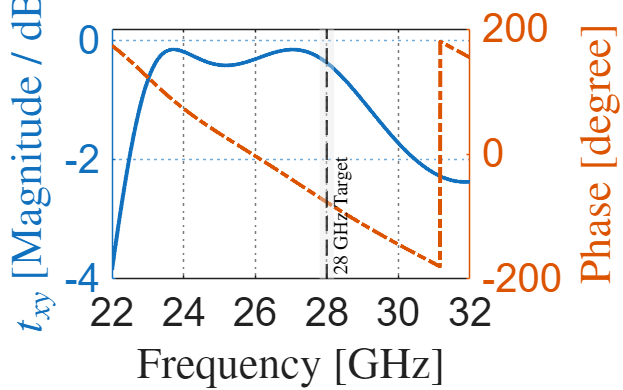

% Extract the frequency and S-Parameter columns
frequency = rawData_dB(:, 1);  % Column 1: Frequency (GHz)
sParameter = rawData_dB(:, 2); % Column 2: Magnitude (dB)
s_phase = rawData_phase(:,2); % Column 2: Phase in degrees

%% 3. Plot Generation
figure('Color', 'w', 'Units', 'pixels', 'Position', [100, 100, 800, 500]);
yyaxis left
plot(frequency, sParameter, 'LineWidth', 2); % Matching CST's red color

ylabel('$t_{xy}$ [Magnitude / dB]', 'FontSize', font, 'Interpreter','latex');
ylim([-4.0, 0.2]);

yyaxis right
plot(frequency,s_phase,'LineStyle','-.','LineWidth',2)
ylabel('Phase [degree]', 'FontSize', font, 'Interpreter','latex');

hold on;
%% 4. Engineering Annotations (Target 28 GHz Window)
% Draw a vertical marker at your 28 GHz center target
xline(28.0, '--k', '$28$ GHz Target', 'LineWidth', 1.2, 'LabelVerticalAlignment', 'bottom','Interpreter','latex');

% Draw a bounding shaded block for your 400 MHz indoor positioning window (27.8 - 28.2 GHz)
patch([27.8 28.2 28.2 27.8], [-200 -200 200 200], [0.9 0.9 0.9], 'FaceAlpha', 0.4, 'EdgeColor', 'none', 'HandleVisibility', 'off');

%% 5. Formatting and Grid Alignment
grid on;
ax = gca;
ax.GridLineStyle = ':';
ax.GridAlpha = 0.6;
box on;

% Label setups
xlabel('Frequency [GHz]', 'FontSize', font,'Interpreter','latex');
ylabel('Phase [degree]', 'FontSize', font, 'Interpreter','latex');

% Force the axis boundaries to frame the exported data cleanly
xlim([min(frequency), max(frequency)]);
 

set(gca,'FontSize',font);

#### Functions

function addingPathParentFolderByName(targetName)
    %Place the matlab directory at the right position
    % Start from the current directory
    currFolder = pwd;
    found = false;
    
    % Continue searching until you reach the root folder
    while true
        % Get the parent folder
        [parentFolder, currentName] = fileparts(currFolder);
        
        % Check if the current folder's name is the target
        if strcmpi(currentName, targetName)
            found = true;
            break;
        end
        
        % If we've reached the root or no change, exit the loop
        if isempty(parentFolder) || strcmp(currFolder, parentFolder)
            break;
        end
        
        % Move one level up
        currFolder = parentFolder;
    end

    if found
        addpath(genpath(currFolder));
        fprintf('Adding matlab path to: %s\n', currFolder);
    else
        error('Folder named "%s" not found in any parent directory.', targetName);
    end
end